# Signal from Aluminum Disk at Varying Distances - Analysis

This analysis uses the rf data that was manually downconverted with no decimation.

clear; clc;
addpath('../functions');

## Choose a center frequency

freq=3;
Fc=7.29e9;

## Plot the signal at all distances

% signal = []; 
% for i=267:517
%     data=obtain_data_manual_downconversion(i, freq);
%     data=abs(data);
%     signal=[signal;data'];
% end
% 
% figure;
% surf(signal, 'LineStyle', 'None');
% title('Signal before baseline subtraction');

## Plot the baseline

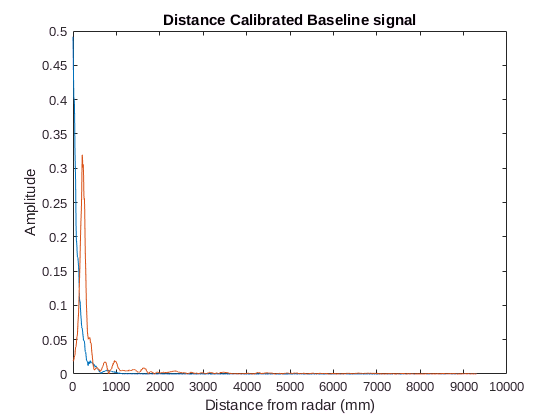

baseline=obtain_baseline_manual_downconversion(freq);
[val_zero index_zero] = max(abs(baseline));
%Shift baseline 
baseline=baseline(index_zero+1:length(baseline));
figure;
plot([0:length(baseline)-1]*(299792458*1000*0.5/(23.328e9)),abs(baseline)); %Plot baseline with any shifting or padding
hold on;

%Obtain and shift data, subtract baseline
data=obtain_data_manual_downconversion(517, freq);
data=data(index_zero+1:length(data));
data=data-baseline;
%Take the absolute value of the complex data
data=abs(data);

plot([0:length(baseline)-1]*(299792458*1000*0.5/(23.328e9)),data);

title('Distance Calibrated Baseline signal');
xlabel('Distance from radar (mm)');
ylabel('Amplitude')

## Plot the signal after baseline subtraction

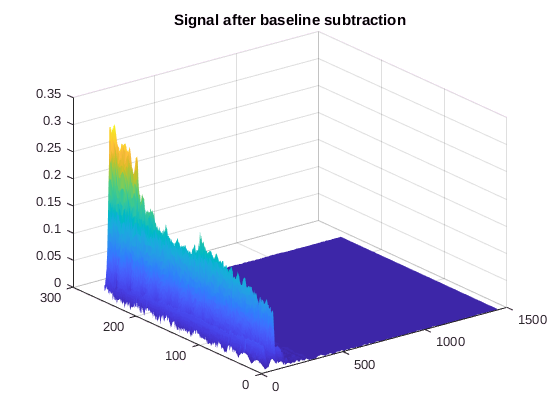

signal = []; 
peaks = [];
peak_locations=[];
for i=267:517
    %Obtain and shift data, subtract baseline
    data=obtain_data_manual_downconversion(i, freq);
    data=data(index_zero+1:length(data));
    data=data-baseline;
    %Take the absolute value of the complex data
    data=abs(data);
    %Get peak of data
    [max_data loc]=max(data);
    peaks=[peaks max_data];
    peak_locations=[peak_locations loc];
    signal=[signal; data];
end

figure;
surf(signal, 'LineStyle', 'None');
title('Signal after baseline subtraction');

## Plot actual distance vs distance from signal

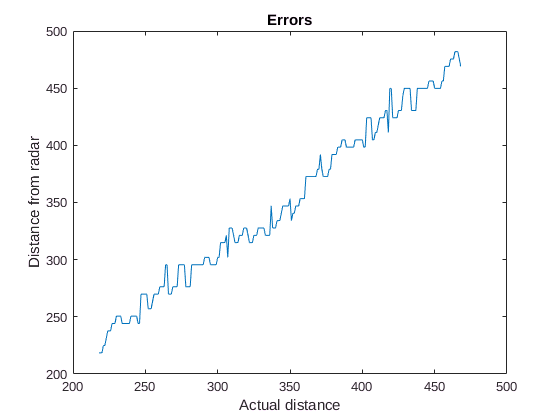

signal_dist=peak_locations.*(299792458*1000*0.5/(23.328e9));
actual_dist=[735-267:-1:735-517];
plot(actual_dist,signal_dist);
title('Errors');
xlabel('Actual distance');
ylabel('Distance from radar');

## Plot absolute error for each distance

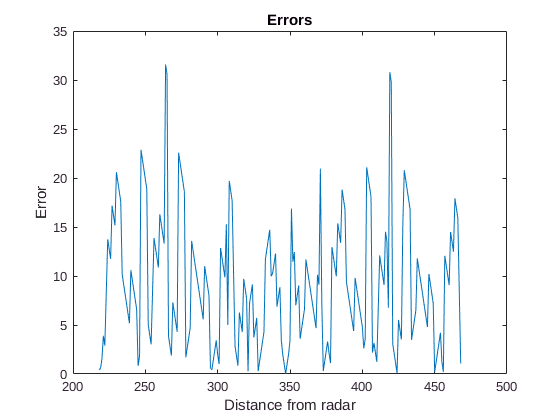

signal_dist=peak_locations.*(299792458*1000*0.5/(23.328e9));
actual_dist=[735-267:-1:735-517];
plot(actual_dist,abs(signal_dist-actual_dist));
title('Errors');
xlabel('Distance from radar');
ylabel('Error');